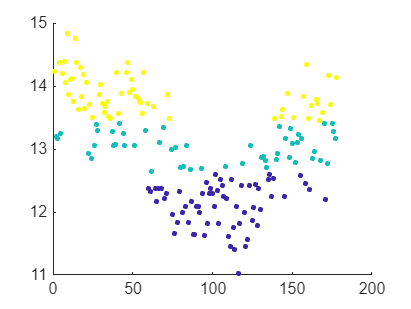

data = readtable('wine-clustering.csv');
X = data{:, 'Alcohol'};
k = 3;
[idx, medoids] = kmedoids(X, k, 'Distance', 'cityblock');
figure;
scatter(1:numel(X), X, 10, idx, 'filled');
hold on;

scatter(medoids, X(medoids), 50, 'k', 'filled');

Array indices must be positive integers or logical values.

xlabel('Point Index');
ylabel('Alcohol');
legend('Data Points', 'Medoids', 'Location', 'best');
hold off;